filename = 'D:\TA mirrors\quartz-air-quartz exp2 fr1.h5';
h5disp(filename);

HDF5 quartz-air-quartz exp2 fr1.h5 
Group '/' 
    Group '/FileType' 
        Attributes:
            'AgilentH5FileType':  'Agilent Waveform'
    Group '/Frame' 
        Attributes:
            'ModelNumber':  'MSO-X 4154A'
            'SerialNumber':  'MY56310590'
            'DateTime':  '09-Feb-2023 21:13:24'
            'SoftwareVersion':  '07.31.2020012900'
    Group '/Waveforms' 
        Attributes:
            'NumWaveforms':  3
        Group '/Waveforms/Channel 1' 
            Attributes:
                'WaveformType':  AVERAGE
                'Start':  0
                'NumPoints':  64516
                'NumSegments':  0
                'Count':  1
                'XDispRange':  0.200000
                'XDispOrigin':  -0.154800
                'XInc':  0.000003
                'XOrg':  -0.154688
                'XUnits':  'Second'
                'YDispRange':  0.800000
                'YDispOrigin':  -0.002500
                'YInc':  0.000013
                'YOrg':  -0

data_CH1 = h5read(filename,'/Waveforms/Channel 1/Channel 1 Data')

data_CH1 = 64516×1 single column vector
   -0.2569
   -0.2535
   -0.2535
   -0.2569
   -0.2535
   -0.2602
   -0.2569
   -0.2535
   -0.2535
   -0.2535


data_Math = h5read(filename,'/Waveforms/Math 2/Math 2 Data')

data_Math = 64516×1 single column vector
    0.0703
    0.0770
    0.0770
    0.0736
    0.0770
    0.0703
    0.0770
    0.0770
    0.0803
    0.0770


data_Ref = h5read(filename,'/Waveforms/WfmMem 1/WfmMem 1 Data')

data_Ref = 64516×1 single column vector
   -0.3272
   -0.3305
   -0.3305
   -0.3305
   -0.3305
   -0.3305
   -0.3339
   -0.3305
   -0.3339
   -0.3305


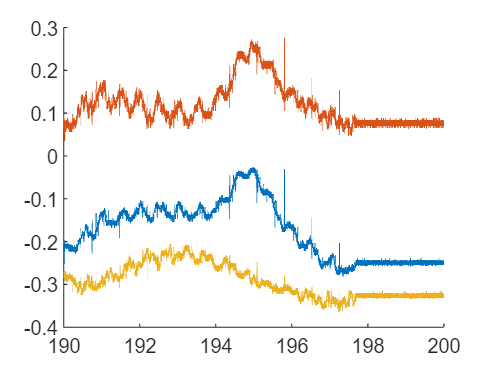

X_inc = h5readatt(filename,'/Waveforms/Math 2','XInc');
X_Axis = (0:X_inc:X_inc*(length(data_Math)-1))';
Sweep_start = 0.0519794;
Sweep_end = 0.396499;
Sweep_index = find(X_Axis > Sweep_start & X_Axis < Sweep_end);
W_start = 190; % GHz
W_end = 200; % GHz
W_inc = (W_end - W_start)/(length(Sweep_index)-1);
X_axis_freq = W_start:W_inc:W_end;
figure
hold on
plot(X_axis_freq,data_CH1(Sweep_index));
plot(X_axis_freq,data_Math(Sweep_index));
plot(X_axis_freq,data_Ref(Sweep_index));
hold off

data_to_save = [X_axis_freq',data_CH1(Sweep_index),data_Math(Sweep_index),data_Ref(Sweep_index)];
[~,fname,~]=fileparts(filename);
save(fname,'data_to_save');

